clear all;
addpath('Convex_src/');
addpath(fullfile('Convex_src/minFunc'));
addpath(fullfile('Convex_src/minFunc_2012'));
addpath(fullfile('Convex_src/minFunc','compiled'));
addpath(fullfile('Convex_src/minFunc','mex'));
addpath('Non_convex_src/');

## Error VS SNR

L = 2^8;
N = 50;
K = 25;
J = 20; % Number of iterations for each point
Convex_SNR = zeros(7,J);
Convex_MSE = zeros(7,J);
for i = 1:7
    for j = 1:J
        idx2 = randperm(L);
        idx2 = idx2(1:K);
        B = speye(L);
        B = B(:,idx2); % Columns random subset of Identity matrix
        % B = B(:,1:K); % First K columns of Identity matrix
        
        scaling = [1 0.5 0.1 0.01 0.001 0.0001 0.00001];
        noise = randn(L,1);
        noise = scaling(i)*noise/norm(noise); 


        m = randn(N,1);
        m= m/norm(m);
        h = randn(K,1);
        h = h/norm(h);
        
        C = randn(L,N)/sqrt(L);
        CC = @(x) C*x;
        CCT = @(x) C'*x;
        BBT = @(x) B'*x;
        BB = @(x) B*x;

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        conv_wx = real(ifft(fft((CC(m))).*fft(BB(h))));
        conv_wx = conv_wx+noise;
        

        [M,H] = blindDeconvolve_implicit(conv_wx,CC,BB,4,CCT,BBT);

        [UM,SM,VM] = svd(M,'econ');
        [UH,SH,VH] = svd(H,'econ');

        [U2,S2,V2] = svd(SM*VM'*VH*SH);
        mEst=sqrt(S2(1,1))*UM*U2(:,1);
        hEst=sqrt(S2(1,1))*UH*V2(:,1);  
        
        Convex_SNR(i,j)  = norm(m*h','fro')^2/norm(noise)^2;
        Convex_MSE(i,j)  = norm(m*h'-mEst*hEst','fro')^2/norm(m)^2/norm(h)^2;
    end
end

|      |          |          | iter  | tot   |
| iter |  rmse    |  sigma   | time  | time  |
----------------------------------------------
|  1   | 3.99e-04 | 1.00e+04 |    1  |    1  |
|  2   | 2.37e-04 | 1.00e+04 |    0  |    1  |
|  3   | 3.57e-05 | 1.00e+05 |    1  |    1  |
|  4   | 5.33e-06 | 1.00e+05 |    0  |    2  |
|  5   | 1.95e-06 | 1.00e+05 |    1  |    2  |
|  6   | 1.17e-06 | 1.00e+05 |    0  |    3  |
|  7   | 1.10e-07 | 1.00e+06 |    0  |    3  |
|  8   | 9.25e-09 | 1.00e+06 |    0  |    3  |
elapsed time: 3 seconds
|      |          |          | iter  | tot   |
| iter |  rmse    |  sigma   | time  | time  |
----------------------------------------------
|  1   | 3.08e-04 | 1.00e+04 |    0  |    0  |
|  2   | 1.89e-04 | 1.00e+04 |    0  |    1  |
|  3   | 3.14e-05 | 1.00e+05 |    0  |    1  |
|  4   | 7.37e-06 | 1.00e+05 |    0  |    1  |
|  5   | 2.82e-06 | 1.00e+05 |    0  |    2  |
|  6   | 1.41e-06 | 1.00e+05 |    0  |    2  |
|  7   | 8.24e-07 | 1.00e+05 |    0 

Convex_SNR_log = 10*log10(sum(Convex_SNR,2)/J);
Convex_MSE_log = 10*log10(sum(Convex_MSE,2)/J);

global A B y L h x

Non_Convex_SNR = zeros(7,J);
Non_Convex_MSE = zeros(7,J);
for i = 1:7
    for j = 1:J
        idx2 = randperm(L);
        idx2 = idx2(1:K);
        B = speye(L);
        B = B(:,idx2); % Columns random subset of Identity matrix
        % B = B(:,1:K); % First K columns of Identity matrix
        
        scaling = [1 0.5 0.1 0.01 0.001 0.0001 0.00001];
        noise = randn(L,1);
        noise = scaling(i)*noise/norm(noise); 


        m = randn(N,1);
        m= m/norm(m);
        h = randn(K,1);
        h = h/norm(h);
        
        N = i*2;
        K = j*2;
        F = dftmtx(L)/sqrt(L);
        B = F(:,1:K);
        h = randn(K,1);
        h = h/norm(h);
        C = randn(L,N)+1i*randn(L,N);
        A = F*C;
        x = randn(N,1);
        x = x/norm(x);
        y =diag(B*h*x'*A')+noise;
        w = 1;
        iter = 2000;
        [u,v] = nonConvexBD(w,x,y,B,C,L,N,K,iter); 
        
        Non_Convex_SNR(i,j)  = norm(h*x','fro')^2/norm(noise)^2;
        Non_Convex_MSE(i,j)  = norm(h*x'-u*v','fro')^2/norm(h*x','fro');
    end
end

 
Calling SDPT3 4.0: 1028 variables, 260 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 260
 dim. of socp   var  = 771,   num. of socp blk  = 257
 dim. of linear var  = 257
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.4e+02|2.1e+01|1.4e+05| 5.484502e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.587|7.1e-05|8.9e+00|1.9e+04| 1.314684e+03 -4.978228e+00| 0:0:00| chol  1  1 
 2|1.000|0.934|3.0e-05|6.2e-01|2.2e+03| 1.140314e+03 -8.541801e-01| 0:0:00| chol  1  1 
 3|1.000|1.000|3.7e-06|3.0e-03

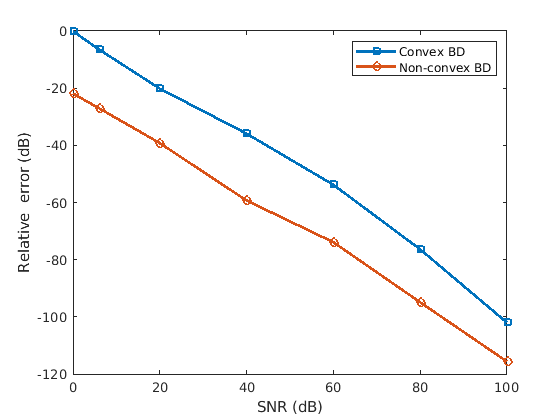

Non_Convex_SNR_log = 10*log10(sum(Non_Convex_SNR,2)/J);
Non_Convex_MSE_log = 10*log10(sum(Non_Convex_MSE,2)/J);

figure;
plot(Convex_SNR_log, Convex_MSE_log, '-s', 'LineWidth',2), xlabel('SNR (dB)'), ylabel('Relative  error (dB)');
hold on;
plot(Non_Convex_SNR_log, Non_Convex_MSE_log, '-o', 'LineWidth',2);
legend('Convex BD', 'Non-convex BD');

clear all;

## Error VS Oversampling

global A B y L h x

N = 20;
K = 10;        
Jt = 20;
Convex_RMS = zeros(25,Jt);
Convex_Oversampling = zeros(25,1);
for i = 1:25
    for j = 1:Jt
        L = 10*i;
        
        idx2 = randperm(L);
        idx2 = idx2(1:K);
        B = speye(L);
        B = B(:,idx2);


        noise = randn(L,1);
        noise = 0.1*noise/norm(noise);


        m = randn(N,1);
        m= m/norm(m);
        h = randn(K,1);
        h = h/norm(h);
        
        C = randn(L,N)/sqrt(L);
        CC = @(x) C*x;
        CCT = @(x) C'*x;

        
        BBT = @(x) B'*x;
        BB = @(x) B*x;
        conv_wx = real(ifft(fft((CC(m))).*fft(BB(h))))+noise; 

        [M,H] = blindDeconvolve_implicit(conv_wx,CC,BB,4,CCT,BBT);

        [UM,SM,VM] = svd(M,'econ');
        [UH,SH,VH] = svd(H,'econ');

        [U2,S2,V2] = svd(SM*VM'*VH*SH);
        mEst=sqrt(S2(1,1))*UM*U2(:,1);
        hEst=sqrt(S2(1,1))*UH*V2(:,1);  
        Convex_Oversampling(i) = L/(N+K);
        Convex_RMS(i,j)  = norm(m*h'-mEst*hEst','fro')/norm(m)/norm(h);
    end
end

|      |          |          | iter  | tot   |
| iter |  rmse    |  sigma   | time  | time  |
----------------------------------------------
|  1   | 4.83e-05 | 1.00e+04 |    0  |    0  |
|  2   | 7.61e-07 | 1.00e+04 |    0  |    1  |
|  3   | 8.81e-08 | 1.00e+04 |    0  |    1  |
|  4   | 6.40e-08 | 1.00e+04 |    0  |    1  |
|  5   | 3.39e-08 | 1.00e+05 |    0  |    1  |
|  6   | 3.27e-08 | 1.00e+05 |    0  |    1  |
|  7   | 2.42e-08 | 1.00e+06 |    0  |    1  |
|  8   | 2.36e-08 | 1.00e+07 |    0  |    1  |
|  9   | 2.57e-10 | 1.00e+08 |    0  |    1  |
elapsed time: 1 seconds
|      |          |          | iter  | tot   |
| iter |  rmse    |  sigma   | time  | time  |
----------------------------------------------
|  1   | 4.05e-05 | 1.00e+04 |    0  |    0  |
|  2   | 4.18e-08 | 1.00e+04 |    0  |    0  |
|  3   | 4.54e-08 | 1.00e+04 |    0  |    0  |
|  4   | 2.86e-08 | 1.00e+05 |    0  |    0  |
|  5   | 4.72e-09 | 1.00e+06 |    0  |    0  |
elapsed time: 0 seconds
|      |    

Convex_RMS = (sum(Convex_RMS,2)/Jt);

Non_Convex_RMS = zeros(25,Jt);
Non_Convex_Oversampling = zeros(25,1);
for i = 1:25
    for j = 1:Jt
        L = 10*i;
        
        idx2 = randperm(L);
        idx2 = idx2(1:K);
        B = speye(L);
        B = B(:,idx2);


        noise = randn(L,1);
        noise = 0.1*noise/norm(noise);


        
        m = randn(N,1);
        m= m/norm(m);
        h = randn(K,1);
        h = h/norm(h);
        
        F = dftmtx(L)/sqrt(L);
        B = F(:,1:K);
        h = randn(K,1);
        h = h/norm(h);
        C = randn(L,N)+1i*randn(L,N);
        A = F*C;
        x = randn(N,1);
        x = x/norm(x);
        y =diag(B*h*x'*A')+noise;
        w = 1;
        iter = 200;
        [u,v] = nonConvexBD(w,x,y,B,C,L,N,K,iter); 
        
        Non_Convex_Oversampling(i) = L/(N+K);
        Non_Convex_RMS(i,j)  = norm(h*x'-u*v','fro')/norm(h)/norm(x);
    end
end

 
Calling SDPT3 4.0: 52 variables, 22 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 22
 dim. of socp   var  = 41,   num. of socp blk  = 11
 dim. of linear var  = 11
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.3e+01|6.1e+00|1.2e+03| 2.507274e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.584|2.6e-06|2.6e+00|4.8e+02| 7.694027e+01 -3.006646e+00| 0:0:01| chol  1  1 
 2|1.000|0.990|6.9e-06|3.3e-02|5.9e+01| 5.356243e+01 -1.862847e+00| 0:0:01| chol  1  1 
 3|0.896|0.934|8.1e-07|2.8e-03|6.1e+0

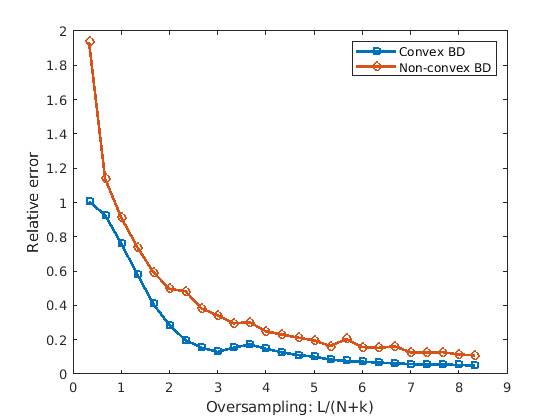


Non_Convex_RMS = (sum(Non_Convex_RMS,2)/Jt);

figure;
plot(Convex_Oversampling, Convex_RMS, '-s', 'LineWidth',2), xlabel('Oversampling: L/(N+k)'), ylabel('Relative error');
hold on;
plot(Non_Convex_Oversampling, Non_Convex_RMS, '-o', 'LineWidth',2);
legend('Convex BD', 'Non-convex BD');